# Training Unit 6: Automatic Code Generation

Fink Lucas / Teichtmeister Marcus, 05.11.2025

## MATLAB Setup

clear
clc

Set LaTex interpreter as default for graphics

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Set font size for graphics

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Change directory (into the live script directory)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Generating a Fibonacci Number Generator

Here you can define, which Fibonacci Number should be calculated:

n = 8;

If n exceeds the value 38 (7.18s) the computation time required will be above 10s (12.68s for 39) on the device used.

tic
nthFiboNum = fibonacciCalculation(n)

nthFiboNum =     21.0000e+000

toc

Elapsed time is 0.002678 seconds.


### Input Parameter Handling

% Testfälle
test_cases = {-1; 'a'; [1, 2]; [2, 1]; 5i; 3.41; "Hello Fibonacci."};

% Iteration durch die Testfälle
for k = 1:size(test_cases, 1)
    n_input = test_cases{k, 1};

    try
        fibonacciCalculation(n_input);
    catch ME
        fprintf('Test successful #%d %s\n', k, ME.message);
    end
end

Test successful #1 Invalid argument at position 1. Value must be nonnegative.
Test successful #2 Invalid argument at position 1. Value must be numeric.
Test successful #3 Invalid argument at position 1. Value must be a scalar.
Test successful #4 Invalid argument at position 1. Value must be a scalar.
Test successful #5 Invalid argument at position 1. Value must be real.
Test successful #6 Invalid argument at position 1. Value must be integer.
Test successful #7 Invalid argument at position 1. Value must be numeric.


clearvars

## Generating a Matlab executable function from your Fibonacci function

The MATLAB Coder successfully generated the MEX function, `fibonacciCalculation_mex`, for the entry-point function `fibonacciCalculation(n)`.

**Examination of the Code Generation Report:**

**Source Logic Files:**

- `fibonacciCalculation.c and fibonacciCalculation.h`

**The Executable:**

- `fibonacciCalculation_mex.mexw64`: This is the final compiled **binary MEX file**. It combines the source logic and the interface code

**Interface and Source Files:**

- Also a lot of interface and source files for MEX-code have been created, handling the conversion of data between MATLAB's native format and simple C data types.

n = 12;

The MEX-function (6.55s for n=43 and 10.89s for n=44) is considerably faster than the MATLAB-function (7.18s for n=38). So the maximum number could be increased from 38 to 43.

tic
nthFiboNum = fibonacciCalculation_mex(n)

nthFiboNum =    144.0000e+000

toc

Elapsed time is 0.002540 seconds.


### Input Parameter Handling for the MEX-Function

% Testfälle
test_cases = {-1; 'a'; [1, 2]; [2, 1]; 5i; 3.41; "Hello Fibonacci."};

% Iteration durch die Testfälle
for k = 1:size(test_cases, 1)
    n_input = test_cases{k, 1};

    try
        fibonacciCalculation_mex(n_input);
    catch ME
        fprintf('Test successful #%d %s\n', k, ME.message);
    end
end

Test successful #1 Value must be nonnegative.
Test successful #2 Incorrect class for expression 'n': expected 'double' but found 'char'.
Test successful #3 Incorrect size for expression 'n': expected [1x1] but found [1x2].
Test successful #4 Incorrect size for expression 'n': expected [1x1] but found [1x2].
Test successful #5 MATLAB expression 'n' is not of the correct complexness.
Test successful #6 Value must be integer.
Test successful #7 Incorrect class for expression 'n': expected 'double' but found 'string'.


When entering false input parameters to the MEX-Function, it bascially behaves the same as the MATLAB-Function. Just the String of the Error Messages differs, but they carry the same meaning.

clearvars

## Function Performance Testing

Now the performance of the MEX-Function and the MATLAB-Function is compared

n = 8; 
num_runs = 10000; 

Arrays that store the single function run times:

matlab_times = zeros(1, num_runs);
mex_times = zeros(1, num_runs);

Function Testing:

%% 1. Performance-Test: MATLAB-Funktion (fibonacciCalculation.m)
for i = 1:num_runs
    tic;
    fibonacciCalculation(n); 
    matlab_times(i) = toc;
end

%% 2. Performance-Test: MEX-Funktion (fibonacciCalculation_mex.mexw64)
for i = 1:num_runs
    tic; 
    fibonacciCalculation_mex(n); 
    mex_times(i) = toc;
end

Calculation of the mean function calculation time over all runs and the time saving in percent when using MEX-Functions instead of MATLAB-Function

% --- Statistical Evaluation ---
mean_matlab_time = mean(matlab_times);
mean_mex_time = mean(mex_times);

std_matlab = std(matlab_times);
std_mex = std(mex_times);

% Calculate time saving in percent
time_saving_percent = ((mean_matlab_time - mean_mex_time) / mean_matlab_time) * 100;
disp(['Mean MATLAB time: ', num2str(mean_matlab_time * 1e6), ' us']);

Mean MATLAB time: 6.2097 us


disp(['Mean MEX time:    ', num2str(mean_mex_time * 1e6), ' us']);

Mean MEX time:    2.9038 us


disp(['Time Saving (using MEX): ', num2str(time_saving_percent), '%']);

Time Saving (using MEX): 53.2378%


### Performance-Visualisation

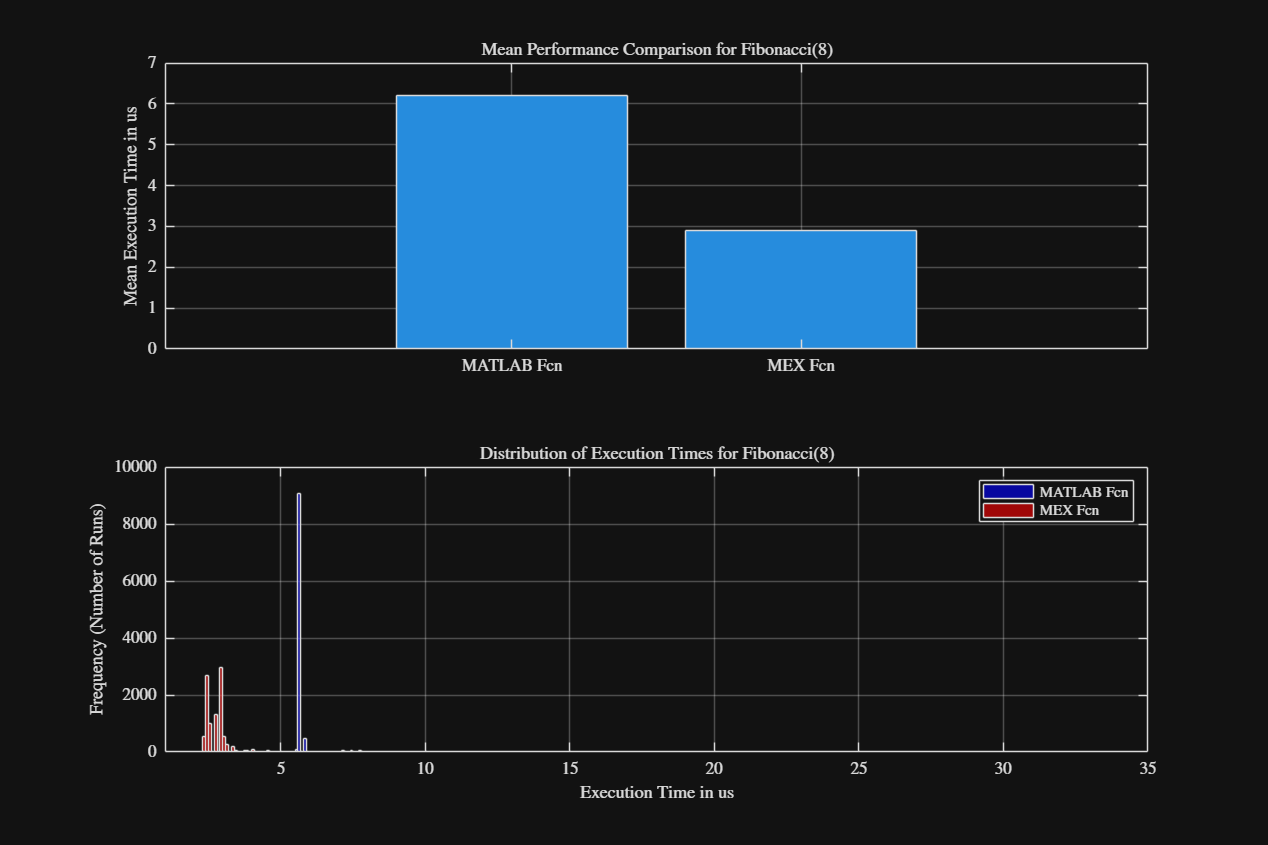

figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
tiledlayout(2,1);

% --- Visualization (Bar Chart) --- 
nexttile
bar_data = [mean_matlab_time, mean_mex_time] * 1e6; 
bar(bar_data);
set(gca, 'XTickLabel', {'MATLAB Fcn', 'MEX Fcn'});
ylabel('Mean Execution Time in us'); 
title(['Mean Performance Comparison for Fibonacci(', num2str(n), ')']);
grid on;
% --- Visualization (Histogram) ---
nexttile
h1 = histogram(matlab_times * 1e6, 'FaceColor', 'b', 'BinWidth', 0.1); 
hold on;
h2 = histogram(mex_times * 1e6, 'FaceColor', 'r', 'BinWidth', 0.1);
legend('MATLAB Fcn', 'MEX Fcn');
xlabel('Execution Time in us');
ylabel('Frequency (Number of Runs)');
title(['Distribution of Execution Times for Fibonacci(', num2str(n), ')']);
xlim([1, 35])
hold off;
grid on;

In the plot above, a huge difference between Execution Time of MATLAB and MEX-functions can be observed. The MEX-function executes around ~90% faster than the MATLAB-function

## Pre-Allocation Testing

Now, the performance benefit of pre-allocating arrays in MATLAB will be demonstrated. First the the fibonacciCalculation will be run without pre-allocation of the storing array an then compared to the pre-allocated version.

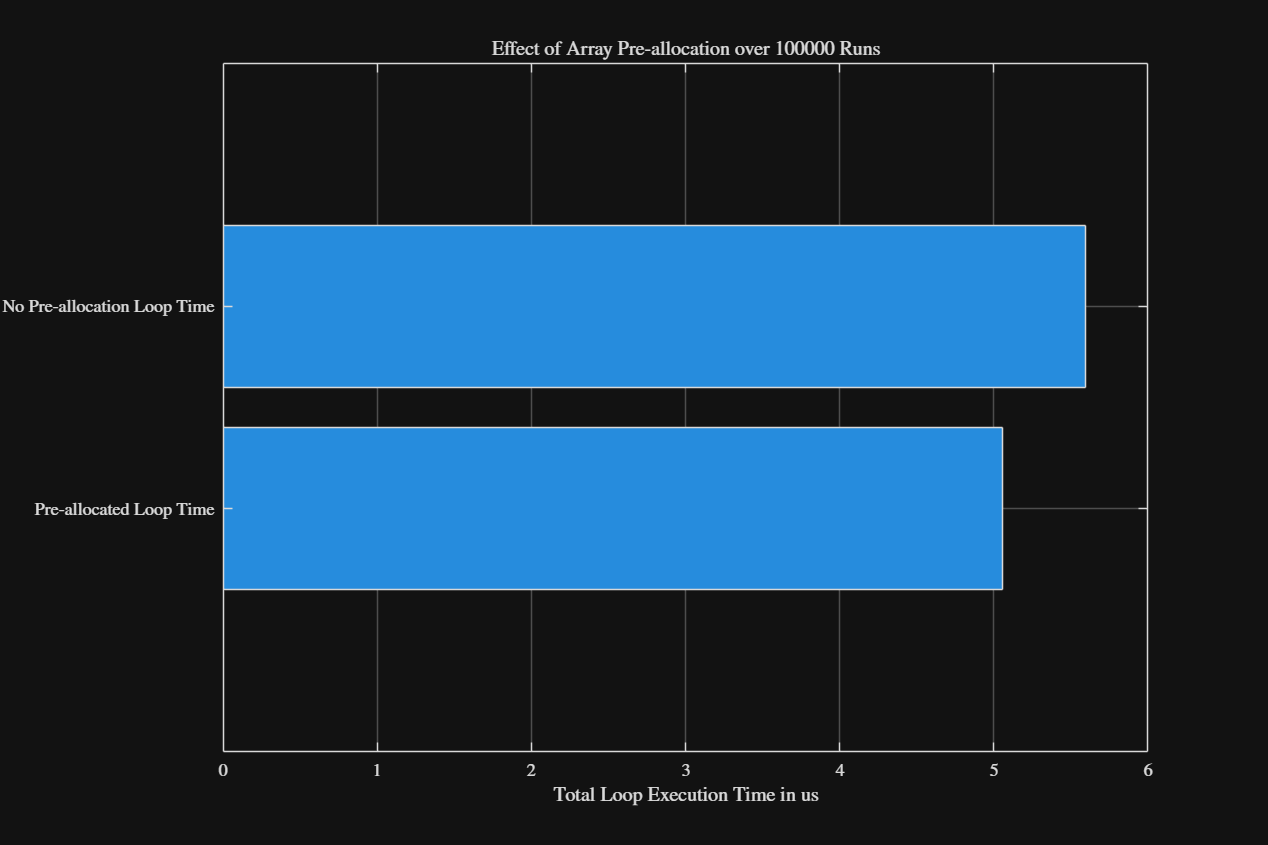

matlab_times_no_prealloc = [];
num_runs_prealloc_test = 100000; 

for i = 1:num_runs_prealloc_test
    tic;
    F_matlab = fibonacciCalculation(n);
    matlab_times_no_prealloc(i) = toc; 
end
mean_matlab_time_no_prealloc = mean(matlab_times_no_prealloc);

matlab_times_prealloc = zeros(1, num_runs_prealloc_test);
for i = 1:num_runs_prealloc_test
    tic;
    F_matlab = fibonacciCalculation(n);
    matlab_times_prealloc(i) = toc;
end
mean_matlab_time_prealloc = mean(matlab_times_prealloc);

% --- Plotting the Effect of Pre-allocation ---
figure('Units', 'normalized', 'Position', [0.2 0.2 0.7 0.7])
barh([mean_matlab_time_prealloc* 1e6, mean_matlab_time_no_prealloc* 1e6]);
set(gca, 'YTickLabel', {'Pre-allocated Loop Time', 'No Pre-allocation Loop Time'});
xlabel('Total Loop Execution Time in us');
title(['Effect of Array Pre-allocation over ', num2str(num_runs_prealloc_test), ' Runs']);
grid on;

disp(['Mean MATLAB time (Pre-allocated): ', num2str(mean_matlab_time_prealloc * 1e6), ' us']);

Mean MATLAB time (Pre-allocated): 5.0544 us


disp(['Mean MATLAB time (No Pre-allocation): ', num2str(mean_matlab_time_no_prealloc * 1e6), ' us']);

Mean MATLAB time (No Pre-allocation): 5.5952 us


clearvars

## Increasing Calculation Load

Now the performance for the MEX and MATLAB-function is tested and compared over an increasing fibonacci number (n)

n_test = [20, 22, 24, 26]; 
num_runs = 250; 

mean_matlab_times = zeros(1, length(n_test));
mean_mex_times= zeros(1, length(n_test));

for k = 1:length(n_test)
    n_current = n_test(k);
    
    time_matlab_current = zeros(1, num_runs);
    time_mex_current = zeros(1, num_runs);
    
    % 1. MATLAB Function Timing
    for i = 1:num_runs
        tic;
        fibonacciCalculation(n_current); 
        time_matlab_current(i) = toc;
    end
    mean_matlab_times(k) = mean(time_matlab_current);
    
    % 2. MEX Function Timing
    for i = 1:num_runs
        tic;
        fibonacciCalculation_mex(n_current); 
        time_mex_current(i) = toc;
    end
    mean_mex_times(k) = mean(time_mex_current);
    
end

### High Load Performance Evaluation

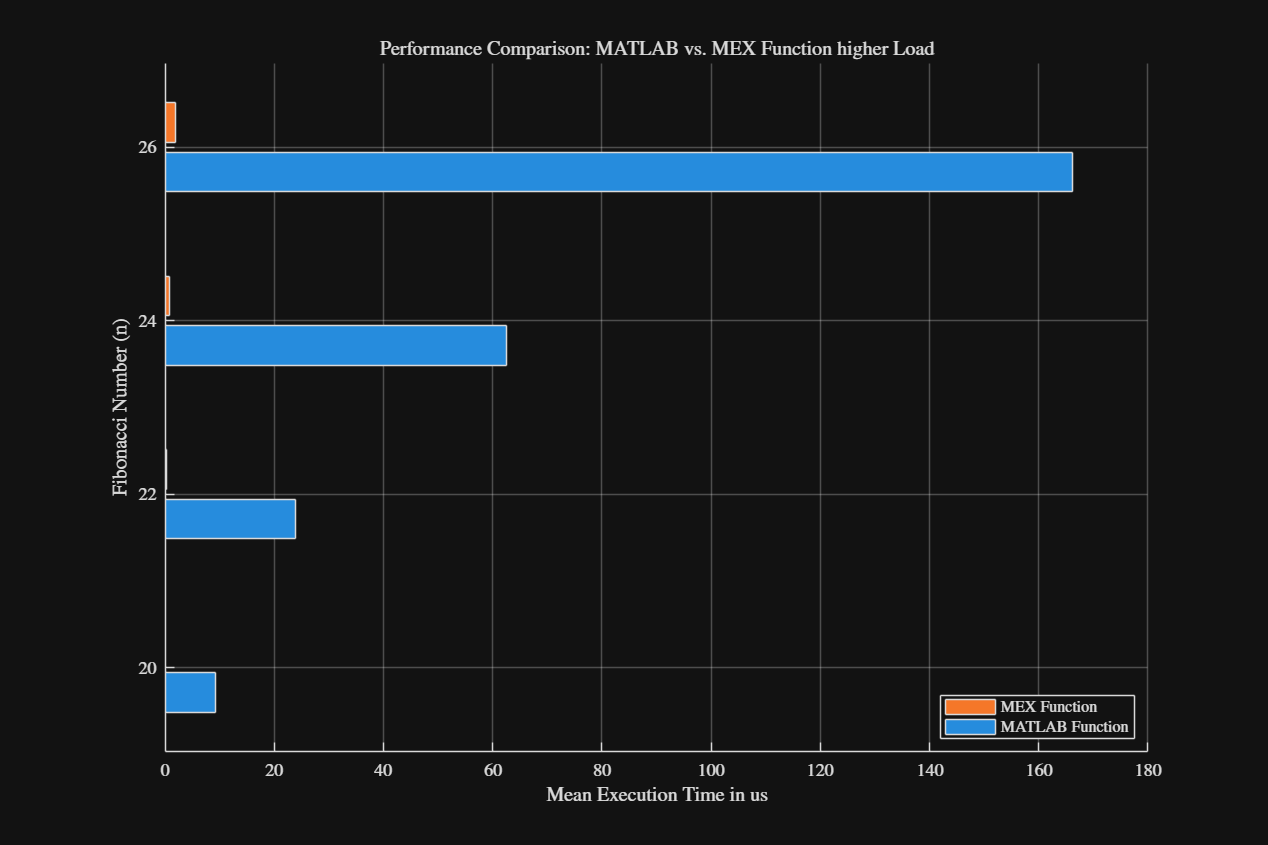

DataMatrix = [mean_matlab_times' * 1000, ...
              mean_mex_times' * 1000]; 

figure('Units', 'normalized', 'Position', [0.1 0.1 0.7 0.7]);
h_bar = barh(DataMatrix); 
yticks(1:length(n_test));
yticklabels(cellstr(num2str(n_test'))); 
xlabel('Mean Execution Time in us');
ylabel('Fibonacci Number (n)');
title('Performance Comparison: MATLAB vs. MEX Function higher Load');
legend({'MATLAB Function', 'MEX Function'}, 'Location', 'SouthEast');
grid on;
box off;

The plot shows that for greater n, the MATLAB-function really soon becomes the limitating factor. 